# 二维SSH模型

[1711.08712 (arxiv.org)](https://arxiv.org/pdf/1711.08712)

#### $\epsilon$: [1, 4] vector： onsite energy, chemical potential included w intra unitcell hopping v inter unitcell hopping

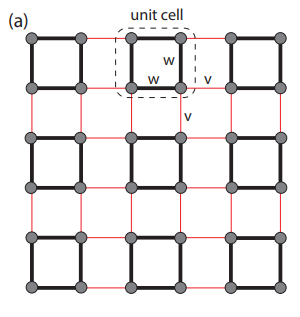

function H = SSH_Model_2D_Real(epsilon,w,v,N_row,N_col)
    H_intra = [epsilon(1), w, w, 0;
               w, epsilon(2), 0, w;
               w, 0, epsilon(3), w;
               0, w, w, epsilon(4)];




## 原胞间跃迁

t_plus: B_n->A_{n+1} 构造横向跃迁元 Transition between column

    temp = get_Nearest_Square_Hopping_Sparse(N_col, N_row, v, 0);
    temp_hori = [0,0,0,0;1,0,0,0;0,0,0,0;0,0,1,0];
    temp = tril(kron(full(temp),temp_hori'));
    H_inter_x = temp + temp';
    
    % 构造纵向跃迁元 Transition between row
    temp = get_Nearest_Square_Hopping_Sparse(N_col, N_row, 0, v);
    temp_vect = [0,0,0,0;0,0,0,0;1,0,0,0;0,1,0,0];
    temp = tril(kron(full(temp),temp_vect'));
    H_inter_y = temp + temp';

    H = kron(eye(N_row*N_col), H_intra) + H_inter_x + H_inter_y;
end